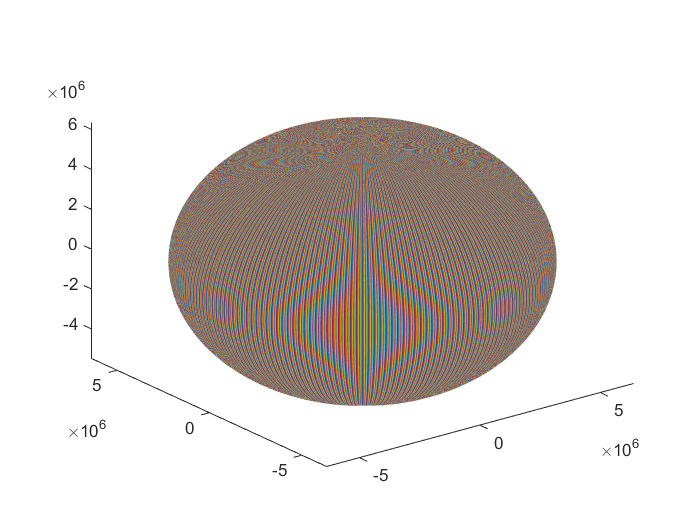

clc;
lat = -59.987: 0.25: 89.875;
lon = -179.875: 0.25: 179.875;

wgs84 = wgs84Ellipsoid('meter');
x = zeros(length(lat), length(lon));
y = zeros(length(lat), length(lon));
z = zeros(length(lat), length(lon));
for i = 1: length(lat)
    for j = 1: length(lon)
        [x(i, j), y(i, j), z(i, j)] = geodetic2ecef(wgs84, lat(i), lon(j), (0 + 40) / 100);
    end
end

writematrix(x, "../input/x_GLDAS_0.25x0.25_1.txt");
writematrix(y, "../input/y_GLDAS_0.25x0.25_1.txt");
writematrix(z, "../input/z_GLDAS_0.25x0.25_1.txt");

plot3(x, y, z)